Jordan Grotz

RBE 501 

Dynamics in Denso HR Robot

3/30/2023

Problem Set 1

[https://www.youtube.com/watch?v=2awZPbrwjtI](https://www.youtube.com/watch?v=2awZPbrwjtI) 

Create the trajectory to mimic the robot's motion in the video and plot joint torques for each joint. Assume the weight of the water is zero. You are free to choose any dimensions, size of the links. Your goal is to master Robotics Toolkit to produce torque inputs to motors.

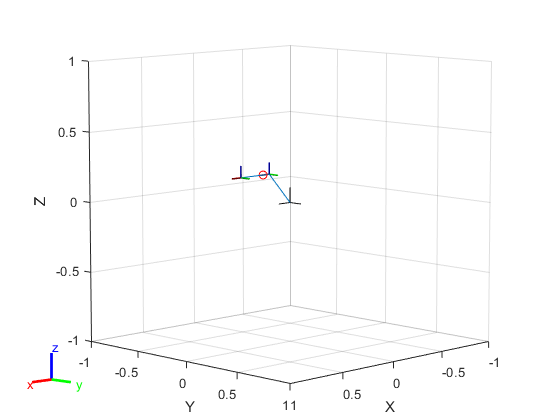

%Denso Robot Creation
%parameters
L1_dimension_x = 0.205; %meters
L1_dimension_z = 0.220;
L2_dimension = 0.275;
R4 = 0.01; %radius of link 4 (the pneumatic gripper)
M1 = 1; %kg
M2 = 1;
M3 = 0.4;
M4 = 0; %joint three and four are the same link
dhparams = [L1_dimension_x, 0 L1_dimension_z 0;
    L2_dimension, 0 0 0;
    0, 0, 0, 0;
    0, 0, 0, 0];

robot = robotics.RigidBodyTree;

body1 = robotics.RigidBody('body1');
jnt1 = robotics.Joint('jnt1','revolute');
body2 = robotics.RigidBody('body2');
jnt2 = robotics.Joint('jnt2','revolute');
body3 = robotics.RigidBody('body3');
jnt3 = robotics.Joint('jnt3','prismatic');
body4 = robotics.RigidBody('body4');
jnt4 = robotics.Joint('jnt4','revolute');


setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

body1.Joint = jnt1;
body1.Mass = M1;
body1.CenterOfMass = [-L1_dimension_x/2 0 0]; %negative because frame is at the end of the link
body1.Inertia = 1/3*M1*L1_dimension_x^2*[1 1 1 0 0 0]; %assumed to be a rod rotated at the end
body2.Joint = jnt2;
body2.Mass = M2;
body2.CenterOfMass = [-L2_dimension/2 0 0];
body2.Inertia = 1/3*M2*L2_dimension^2*[1 1 1 0 0 0]; %assumed to be a rod rotated at the end
body3.Joint = jnt3;
body3.Mass = M3;
body3.CenterOfMass = [0 0 0];
body3.Inertia = [0 0 0 0 0 0];% no intertia
body4.Joint = jnt4;
body4.Mass = M4;
body4.CenterOfMass = [0 0 0];
body4.Inertia = 1/3*M3*[0 0 0 0 0 0]; %mass of joint 3 rotates around center of cylinder

addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');
addBody(robot,body4,'body3');

robot.DataFormat = 'row';
robot.Gravity = [0 0 -9.81]; %z direction

config = [0, 0, 0, 0];

comPos = centerOfMass(robot, config);
figure;
show(robot, config);
hold on
plot3(comPos(1),comPos(2), comPos(3),'or');
hold off

Motion profile 1 Description:

The following motion profiles were observed from the video. The profiles are calculated in the joint space. The profiles are described below. The motions are quick, assumed to be like 1 second of motion time.

1.) Rotation to the left, pick up water bottles, rotate back to center drop water bottles.

2.) Rotation to the left, pick up water bottles, rotate back to center drop water bottles.

Motion profile 2 Description:

1.) Start in center and pick up water bottles, and deposit on the sides.

Key Primatives:

Quick motion from the center to the sides. 

Slowly picking up the water bottles

returning to the center position.

A function was created to take the position, velocity, and acceleration of the motion profile, and use the inverse dynamics to calcuate the joint torques needed.


%Trajectories
%primative one
p1_q1_waypoints = [0, pi/4, 0];
p1_q2_waypoints = [0, pi/2, 0];
zero_waypoints = [0 0 0];
p1_motion_time = 1; %second per waypoint

joint_waypoints = [p1_q1_waypoints; p1_q2_waypoints; zero_waypoints; zero_waypoints];
disp("Motion Primative 1 Joint Position, Velocity, Torque vs Time")

Motion Primative 1 Joint Position, Velocity, Torque vs Time


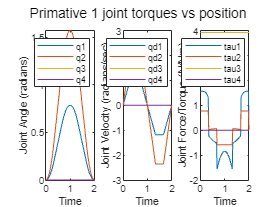

plot_trajectory_torques(joint_waypoints, p1_motion_time, robot, "Primative 1 joint torques vs position");



%primative 2
p2_q3_waypoints = [0,-0.5,0];
p2_motion_time = 3; %seconds
joint_waypoints2 = [zero_waypoints; zero_waypoints; p2_q3_waypoints; zero_waypoints];
disp("Motion Primative 2 Joint Position, Velocity, Torque vs Time")

Motion Primative 2 Joint Position, Velocity, Torque vs Time


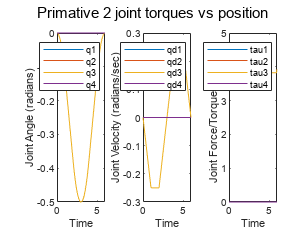

plot_trajectory_torques(joint_waypoints2, p2_motion_time, robot, "Primative 2 joint torques vs position");



%primative 3
p3_q1_waypoints = [-pi/4, 0, -pi/4];
p3_q2_waypoints = [-pi/2, 0, pi/2];
p3_motion_time = 1; %second
joint_waypoints = [p3_q1_waypoints; p3_q2_waypoints; zero_waypoints; zero_waypoints];
disp("Motion Primative 3 Joint Position, Velocity, Torque vs Time")

Motion Primative 3 Joint Position, Velocity, Torque vs Time


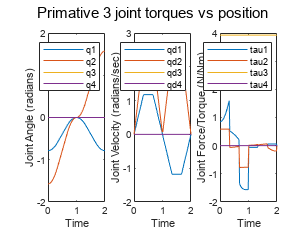

plot_trajectory_torques(joint_waypoints, p3_motion_time, robot, "Primative 3 joint torques vs position");

Problem set 2

 Calculate the external force immediately after the robot picks up the water, and compute joint torques required to balance the external forces. 

Slow motion to pickup bottle assumes no inertial forces. So it can be a static analysis problem. The external force function uses the jacobian to translate an external force to joint forces and torques. This is then applied in the inverseDynamics equation to understand what forces/torques the robot needs to produce to balance the external forces given the position and velocity states.

water_mass = 5; %kg
water_force = -9.81*water_mass;
wrench = [0 0 0 0 0 water_force];
pickup_config = [0,0,-0.5,0];
fext = externalForce(robot, "body3",wrench, pickup_config)

fext =          0         0         0         0         0         0
         0         0         0         0         0         0
         0   23.5440         0         0         0  -49.0500
         0         0         0         0         0         0


joint_torques_water = inverseDynamics(robot,pickup_config,[0 0 0 0], [0 0 0 0], fext)

joint_torques_water =          0         0   52.9740         0


Problem set 3

Plot the joint torques required to balance the external forces while the robot is in motion.

    An additional function is created that caculates the external forces on each joint (given the current joint configuration). This external force is then passed to the inverse dynamics function used previously to showcase the torques/forces needed for the set motion and external load. The same trajectories as in Problem Set 1 are used. 

%Trajectories
%primative one
p1_q1_waypoints = [0, pi/4, 0];
p1_q2_waypoints = [0, pi/2, 0];
zero_waypoints = [0 0 0];
p1_motion_time = 1; %second per waypoint

%exeternal load
water_mass = 2; %kg reduced weight of water from part 2.
water_force = -9.81*water_mass;
wrench = [0 0 0 0 0 water_force];

joint_waypoints = [p1_q1_waypoints; p1_q2_waypoints; zero_waypoints; zero_waypoints];
disp("Motion Primative 1 Joint Position, Velocity, Torque vs Time with external Force")

Motion Primative 1 Joint Position, Velocity, Torque vs Time with external Force


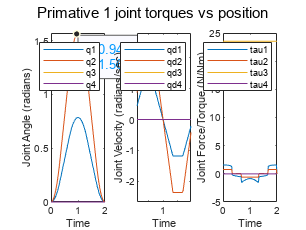

plot_trajectory_torques_with_fext(joint_waypoints, p1_motion_time, robot, "Primative 1 joint torques vs position with external Force",wrench);



%primative 2
p2_q3_waypoints = [0,-0.5,0];
p2_motion_time = 3; %seconds
joint_waypoints2 = [zero_waypoints; zero_waypoints; p2_q3_waypoints; zero_waypoints];
disp("Motion Primative 2 Joint Position, Velocity, Torque vs Time with external Force")

Motion Primative 2 Joint Position, Velocity, Torque vs Time with external Force


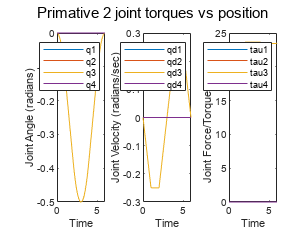

plot_trajectory_torques_with_fext(joint_waypoints2, p2_motion_time, robot, "Primative 2 joint torques vs position with external Force",wrench);



%primative 3
p3_q1_waypoints = [-pi/4, 0, -pi/4];
p3_q2_waypoints = [-pi/2, 0, pi/2];
p3_motion_time = 1; %second
joint_waypoints = [p3_q1_waypoints; p3_q2_waypoints; zero_waypoints; zero_waypoints];
disp("Motion Primative 3 Joint Position, Velocity, Torque vs Time with external Force")

Motion Primative 3 Joint Position, Velocity, Torque vs Time with external Force


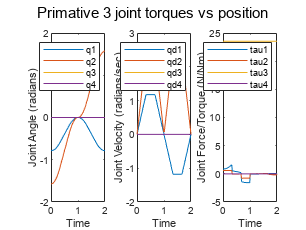

plot_trajectory_torques_with_fext(joint_waypoints, p3_motion_time, robot, "Primative 3 joint torques vs position with external Force",wrench);

Creates a trapezoidal trajectory through the given waypoints for each joint, and calculates the inverser dynamics for each step. Then plots them.

function plot_trajectory_torques(joint_waypoints, motion_time, robot, plot_title)
    %find trajectory profile for each joint
    [q1,q1d,q1dd,ts,pp1] = trapveltraj(joint_waypoints(1,:),100,EndTime=motion_time);
    [q2,q2d,q2dd,ts2,pp2] = trapveltraj(joint_waypoints(2,:),100,EndTime=motion_time);
    [q3,q3d,q3dd,ts3,pp3] = trapveltraj(joint_waypoints(3,:),100,EndTime=motion_time);
    [q4,q4d,q4dd,ts4,pp4] = trapveltraj(joint_waypoints(4,:),100,EndTime=motion_time);
    
    joint_torques = zeros(length(q1),4);
    qs = [q1' q2' q3' q4'];
    qds = [q1d' q2d' q3d' q4d'];
    qdds = [q1dd' q2dd' q3dd' q4dd'];
    %iterate through each joint, and calculate the torques required.
    for i = 1:length(q1)
        joint_torques(i,:) = inverseDynamics(robot,qs(i,:), qds(i,:),qdds(i,:));
    end
    %plotting
    figure;
    sgtitle(plot_title);
    subplot(1,3,1);
    plot(ts', qs);
    xlabel("Time");
    ylabel("Joint Angle (radians)");
    legend(["q1", "q2", "q3", "q4"]);

    subplot(1,3,2);
    plot(ts', qds);
    xlabel("Time");
    ylabel("Joint Velocity (radians/sec)");
    legend(["qd1", "qd2", "qd3", "qd4"]);
    
    subplot(1,3,3);
    plot(ts', joint_torques);
    xlabel("Time");
    ylabel("Joint Force/Torque (N/Nm)");
    legend(["tau1", "tau2", "tau3", "tau4"]);

end



Creates a trapezoidal trajectory through the given waypoints for each joint, and calculates the inverser dynamics for each step, but also accounts for external force in the system. Then plots them.

function plot_trajectory_torques_with_fext(joint_waypoints, motion_time, robot, plot_title,external_wrench)
    %find trajectory profile for each joint
    [q1,q1d,q1dd,ts,pp1] = trapveltraj(joint_waypoints(1,:),100,EndTime=motion_time);
    [q2,q2d,q2dd,ts2,pp2] = trapveltraj(joint_waypoints(2,:),100,EndTime=motion_time);
    [q3,q3d,q3dd,ts3,pp3] = trapveltraj(joint_waypoints(3,:),100,EndTime=motion_time);
    [q4,q4d,q4dd,ts4,pp4] = trapveltraj(joint_waypoints(4,:),100,EndTime=motion_time);
    
    joint_torques = zeros(length(q1),4);
    qs = [q1' q2' q3' q4'];
    qds = [q1d' q2d' q3d' q4d'];
    qdds = [q1dd' q2dd' q3dd' q4dd'];
    %iterate through each point and calcuate torques with external force.
    for i = 1:length(q1)
        fext = externalForce(robot, "body3", external_wrench, qs(i,:));
        joint_torques(i,:) = inverseDynamics(robot,qs(i,:), qds(i,:),qdds(i,:),fext);
    end
    %plotting
    figure;
    sgtitle(plot_title);
    subplot(1,3,1);
    plot(ts', qs);
    xlabel("Time");
    ylabel("Joint Angle (radians)");
    legend(["q1", "q2", "q3", "q4"]);

    subplot(1,3,2);
    plot(ts', qds);
    xlabel("Time");
    ylabel("Joint Velocity (radians/sec)");
    legend(["qd1", "qd2", "qd3", "qd4"]);
    
    subplot(1,3,3);
    plot(ts', joint_torques);
    xlabel("Time");
    ylabel("Joint Force/Torque (N/Nm)");
    legend(["tau1", "tau2", "tau3", "tau4"]);

end
